alpha=1+mod(273,3);

alpha = 1

## Problem 1

%Specify the parameters
sampling_rate=720;
Rp=-(alpha);
Wp=10/(sampling_rate/2);   %Edge frequencies are always normalized wrt sampling rate
Rs=40;
Ws=20/(sampling_rate/2);

%Find the butterworth filter order
[n,Wn]=buttord(Wp, Ws, Rp, Rs);

%Design the butterworth filter
[b,a]=butter(n, Wn,"low");

%Generate the transfer function
syms z
numer=poly2sym(b, z);
denom=poly2sym(a, z);
H=numer/denom

$$H = \frac{\frac{3095667723044241\,z^{7}}{9671406556917033397649408}+\frac{2708709257663711\,z^{6}}{1208925819614629174706176}+\frac{8126127772991133\,z^{5}}{1208925819614629174706176}+\frac{6771773144159277\,z^{4}}{604462909807314587353088}+\frac{6771773144159277\,z^{3}}{604462909807314587353088}+\frac{8126127772991133\,z^{2}}{1208925819614629174706176}+\frac{2708709257663711\,z}{1208925819614629174706176}+\frac{3095667723044241}{9671406556917033397649408}}{z^{7}-\frac{3711535707064607\,z^{6}}{562949953421312}+\frac{5246776722486955\,z^{5}}{281474976710656}-\frac{515375420871271\,z^{4}}{17592186044416}+\frac{1945064072245045\,z^{3}}{70368744177664}-\frac{2203468221243953\,z^{2}}{140737488355328}+\frac{2775060475563917\,z}{562949953421312}-\frac{5994469902942157}{9007199254740992}}$$


%Find the poles of the filter
[z,p,k]=tf2zpk(b,a);
p

p =    0.9763 + 0.0864i
   0.9763 - 0.0864i
   0.9427 + 0.0669i
   0.9427 - 0.0669i
   0.9209 + 0.0363i
   0.9209 - 0.0363i
   0.9133 + 0.0000i


if all(abs(p) < 1)
    fprintf('The system is stable.\n');
else
    fprintf('The system is unstable.\n');
end

The system is stable.



%Plot the pole zero plot
sys=tf(b,a,1/sampling_rate);
pzplot(sys)

Error using  == 
Matrix dimensions must agree.

Error in matlab.internal.editor.FigureManager

Error in matlab.internal.editor.FigureManager.figureBeingCleared

Error in matlab.graphics.internal.clearNotify (line 47)
        matlab.internal.editor.FigureManager.figureBeingCleared(fig, flag);

Error in 

grid on;

%Plot the impulse and step response
impulse(sys, 1);
hold on;
step(sys, 1);
hold off;
grid on;
legend("Impulse","Step");

%Plot the bode plot
freq_spec=linspace(0,50,1e3);
bode(sys, 2*pi*freq_spec);
title("Bode Plot (Magnitude and Phase)");
grid on;

## Problem 2

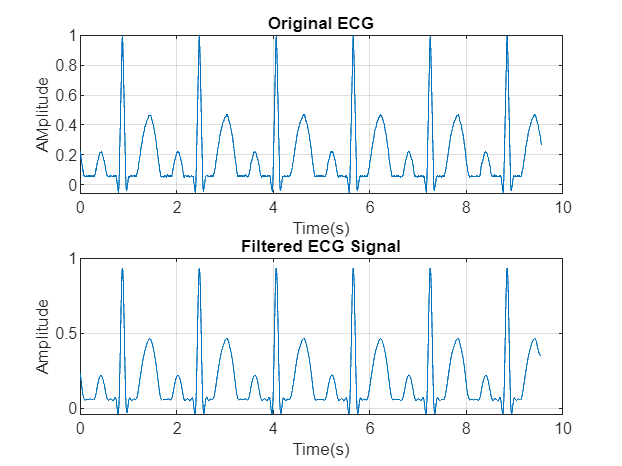

%Import the data
ECG_data=load("ECG_Data.txt");

%Apply the butterworth filter
fitlered_ecg=filtfilt(b,a,ECG_data);

% Create time vector for plotting
time=(0:length(ECG_data)-1)/sampling_rate;

%Plot the original and filtered signals
subplot(2,1,1)
plot(time, ECG_data);
title("Original ECG");
xlabel("Time(s)");
ylabel("AMplitude");
grid on;
subplot(2,1,2);
plot(time, fitlered_ecg);
title("Filtered ECG Signal");
xlabel("Time(s)");
ylabel("Amplitude");
grid on;

## Problem 3

%Specify the parameters
[y, Fs]=audioread("instru1.wav");
window_size=1024;
overlap=window_size/2;

%Calculate the spectrogram
[S,F,T]=spectrogram(y, hamming(window_size), overlap, [], Fs);

%Design the butterworth band pass filter
f_cuttoff= 1500;
bandwidth=100;
[n, Wn]=buttord(bandwidth/(Fs/2), f_cuttoff/(Fs/2), Rp, Rs);

Unrecognized function or variable 'Rp'.

[b,a]=butter(1, [(f_cuttoff- bandwidth/2) (f_cuttoff+bandwidth/2)]/(Fs/2), "bandpass");

%Apply the filter to the signal
filtered_signal=filter(b,a,y);
[S_filtered, ~,~]=spectrogram(filtered_signal, hamming(window_size), overlap, [], Fs);

%Plot both the original and filtered signal
subplot(2,1,1)
imagesc(T,F, 10*log10(abs(S)))
axis xy
colormap jet;
title("Original Spectrogram")
xlabel("Time(s)");
ylabel("Frequency(Hz)");
colorbar;

subplot(2,1,2)
imagesc(T,F,10*log10(abs(S_filtered)))
axis xy
colormap jet;
title("Filtered Spectrogram");
xlabel("Time(s)");
ylabel("Frequency(Hz)");
colorbar;

%Save the file in WAV format
audiowrite("filtered_output.wav", filtered_signal, Fs);

%Listen to the file
%sound(y, Fs)
sound(filtered_signal, Fs)

## Problem 4

%Design the Chebyshev filter
[N,W]=cheb1ord(Wp, Ws, Rp, Rs);

Unrecognized function or variable 'Wp'.

[zero, pole]=cheby1(N, -Rp, Wp);
fprintf("Butterworth Order: %d", n);
fprintf("Chebyshev Order: %d", N);

%Plot the bode plots of both the figures
bode(sys);
hold on;
bode(tf(zero, pole, 1/sampling_rate));
hold off;
grid on;
title("Bode Comparison of the two filters");
legend("Butterworth", "Chebyshev");

%Plot the impulse and step response of the two filters
subplot(2,1,1);
impulse(sys, 1);
hold on;
impulse(tf(zero, pole, 1/sampling_rate), 1);
hold off;
grid on;
legend("Butterworth","Chebyshev");

subplot(2,1,2);
step(sys, 1);
hold on;
step(tf(zero, pole, 1/sampling_rate), 1);
hold off;
grid on;
legend("Butterworth", "Chebyshev");